# Read Different Types of Data

Load the data file and read each column with the appropriate type.

Load file `scan1.dat` and preview its contents in a text editor. A screen shot is shown below.

 filename = 'scan1.dat';

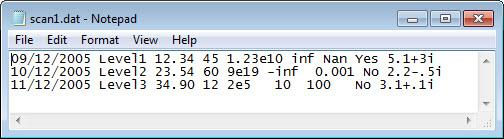

Open the file, and read each column with the appropriate conversion specifier. `textscan` returns a `1-by-9` cell array `C`.

fileID = fopen(filename);
C = textscan(fileID,'%s %s %f32 %d8 %u %f %f %s %f');
fclose(fileID);
whos C

View the MATLAB® data type of each of the cells in `C`. 

C

Examine the individual entries. Notice that `C{1}` and `C{2}` are cell arrays. `C{5}` is of data type `uint32`, so the first two elements of `C{5}` are the maximum values for a `32`-bit unsigned integer, or `intmax('uint32')`.

celldisp(C)

*Copyright 2012 The MathWorks, Inc.*